# Image classification using Convolutional Neural Network [MATLAB]

**Author**: Vineet Jacob Kuruvilla, PhD

**Company**: MathWorks

**Date**: 8th March 2020

**Intended audience**: Beginners

**Project Description**

The purpose of this project is to show an example of how to use Convolutional Neural Network for image classification tasks. In this project, I have used dog and cat image dataset to classify whether the image is that of a dog or a cat. There are two way to go about this task- 1) Transfer Learning ie., to use a pretrained network and, 2) Design your own CNN. I have used the approach #2 in this project.

What you'll learn:

- Using datastore

- Augmenting image data for produce more training data than originally available

- Defining a CNN architecture (here only the programmatic way is shown. I used the Deep Network Designer App to build the network. It saves a lot of time.)

- Setting the training parameters (also enabling parallel computing option)

- Finally, testing the accuracy of the trained network using test data

**Products used**

MATLAB 9.7

Deep Learning Toolbox13.0

Machine Learning and Statistics 11.6

Parallel Computing Toolbox 7.1

## **Code and Outputs**

Load data from data folder.

The dataset was obtained from Kaggle: [https://www.kaggle.com/chetankv/dogs-cats-images](https://www.kaggle.com/chetankv/dogs-cats-images)

clear
data_loc = ".\dataset\training_set";
dt = datastore(data_loc,'IncludeSubfolders',true,"LabelSource","foldernames");

Read data and visualize

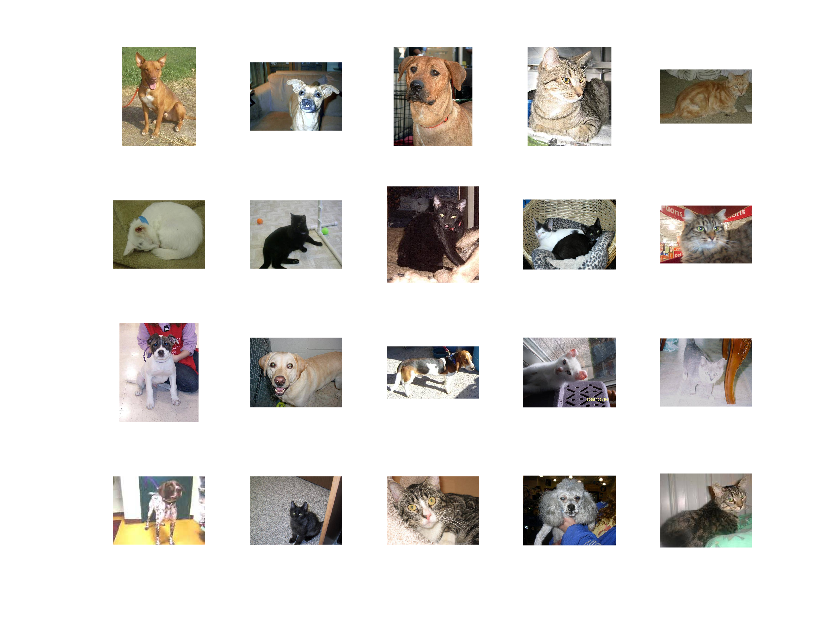

figure;
perm = randperm(8000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(dt.Files{perm(i)});
end

Preprocessing and Data augmentation

labelCount = countEachLabel(dt)

labelCount = 2×2 table
    Label    Count
    _____    _____

    cats     4000 
    dogs     4000 


Create variable to set the input size of the CNN. This variable will be used to resize the training and test images as well.

input_size = [56,56];

Check the test data

data_loc = ".\dataset\test_set";
dtest = datastore(data_loc,'IncludeSubfolders',true,"LabelSource","foldernames");
labelCount_test = countEachLabel(dtest)

labelCount_test = 2×2 table
    Label    Count
    _____    _____

    cats     1000 
    dogs     1000 


Split data into train and validation

Also resize and augment the available training data.

numTrainFiles = 3600;
[dtrain,dValidation] = splitEachLabel(dt,numTrainFiles,'randomize');

pixelRange = [-3 3];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandRotation',[-20,20], ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);

augtrain = augmentedImageDatastore(input_size,dtrain,'ColorPreprocessing','rgb2gray','DataAugmentation',imageAugmenter);
% We don't need to augment the validation test
augValidation = augmentedImageDatastore(input_size,dValidation,'ColorPreprocessing','rgb2gray','DataAugmentation',imageAugmenter);

Define the network architecture

filter_size = [3,3];
layers = [
    imageInputLayer(input_size,"Name","imageinput","Normalization","zerocenter")
    
    convolution2dLayer(filter_size,8,"Name","conv_1","Padding","same")
    batchNormalizationLayer
    reluLayer("Name","relu_1")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Padding","same",'Stride',2)
        
    convolution2dLayer(filter_size,16,"Name","conv_2","Padding","same")
    batchNormalizationLayer
    reluLayer("Name","relu_2")
    maxPooling2dLayer([2 2],"Name","maxpool_2","Padding","same",'Stride',2)
        
    convolution2dLayer(filter_size,32,"Name","conv_3","Padding","same")
    batchNormalizationLayer
    reluLayer("Name","relu_3")
    maxPooling2dLayer([2 2],"Name","maxpool_3","Padding","same",'Stride',2)
        
    convolution2dLayer(filter_size,64,"Name","conv_4","Padding","same")
    batchNormalizationLayer
    reluLayer("Name","relu_4")
    maxPooling2dLayer([2 2],"Name","maxpool_4","Padding","same",'Stride',2)
        
    convolution2dLayer(filter_size,128,"Name","conv_5","Padding","same")
    batchNormalizationLayer
    reluLayer("Name","relu_5")
    maxPooling2dLayer([2 2],"Name","maxpool_5","Padding","same",'Stride',2)
        
    convolution2dLayer(filter_size,256,"Name","conv_6","Padding","same")
    batchNormalizationLayer
    reluLayer("Name","relu_6")
    maxPooling2dLayer([2 2],"Name","maxpool_6","Padding","same",'Stride',2)
        
    fullyConnectedLayer(10,"Name","fc_2_2")
    reluLayer("Name","relu_5_2")
        
    fullyConnectedLayer(2,"Name","fc_3")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

Specify training options.

Parallel Computing Toolbox was used to accelerate the training process. It was trained on quad core Intel Core i7 8th Gen PC.

options = trainingOptions('sgdm','Momentum',0.85, ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',50, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',true, ...
    'Plots','training-progress',...
    'ExecutionEnvironment',"parallel");

Training the neural network

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


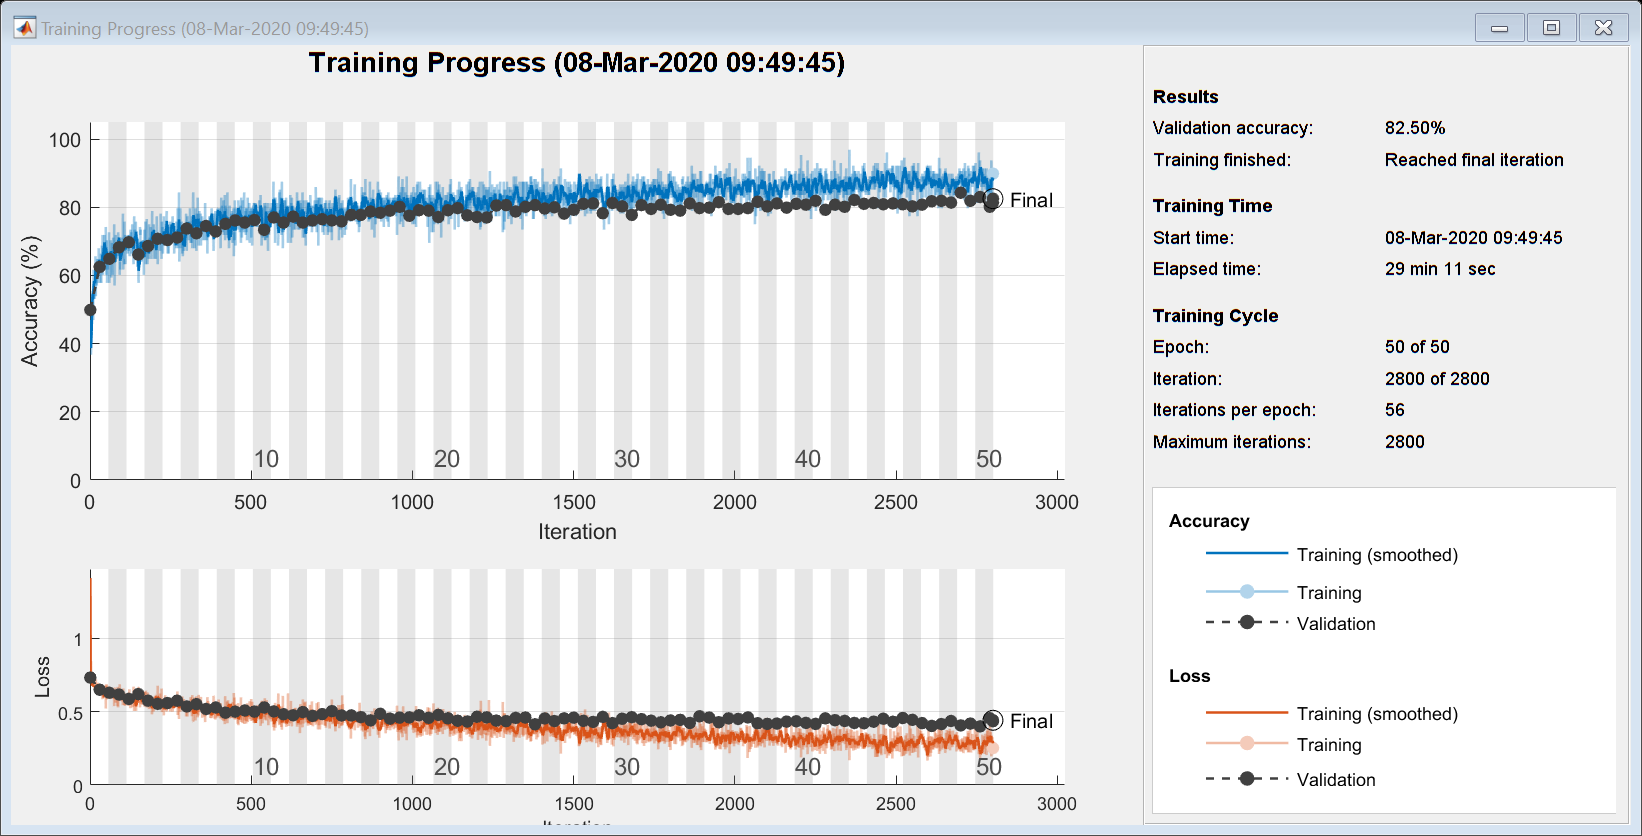

Training across multiple CPUs.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


net = trainNetwork(augtrain,layers,options);

Test the accuracy of the trained network.

Resize the test images to match the network input size and then use the trained network to predict whether the image in the test images represent a dog or a cat

augdtest = augmentedImageDatastore(input_size,dtest,'ColorPreprocessing','rgb2gray');
YPred = classify(net,augdtest);
Ytest = dtest.Labels;


accuracy = 0.8315

accuracy = sum(YPred == Ytest)/numel(Ytest)